# Test 2

## Problema 1

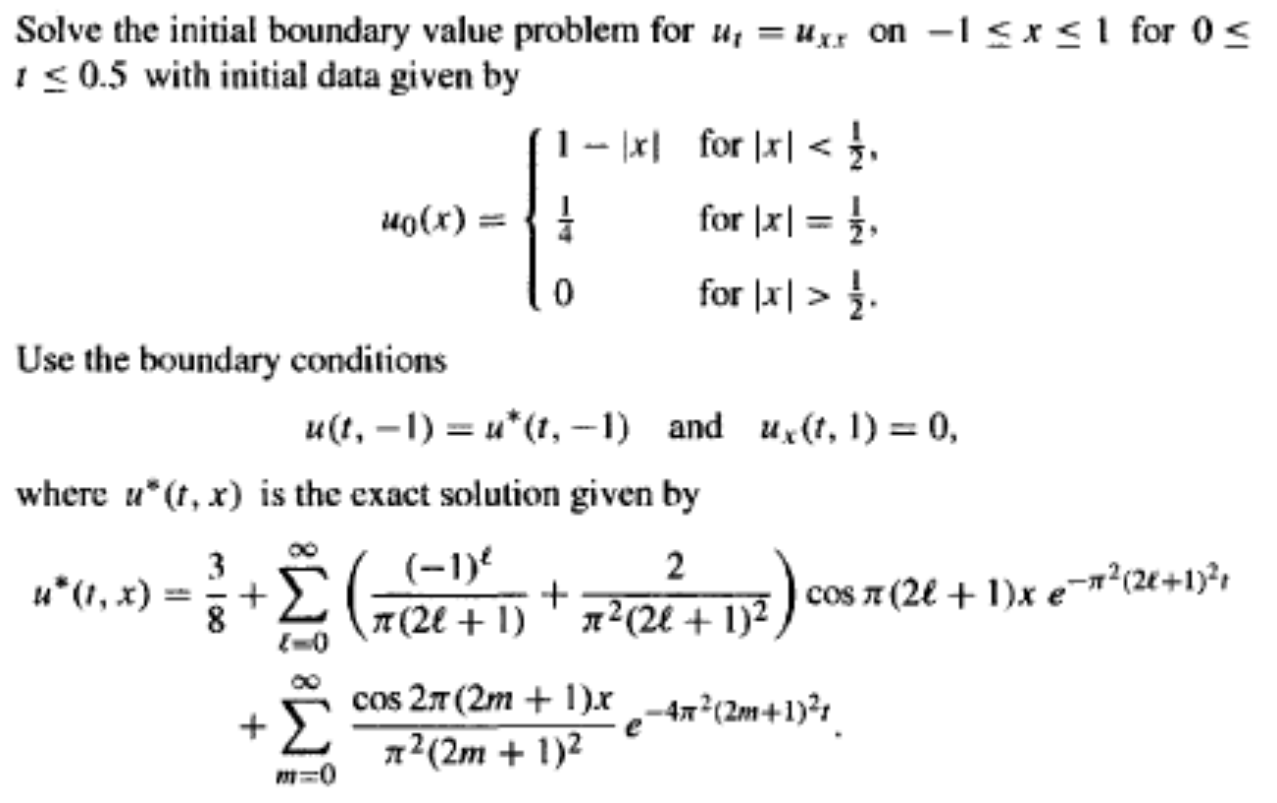

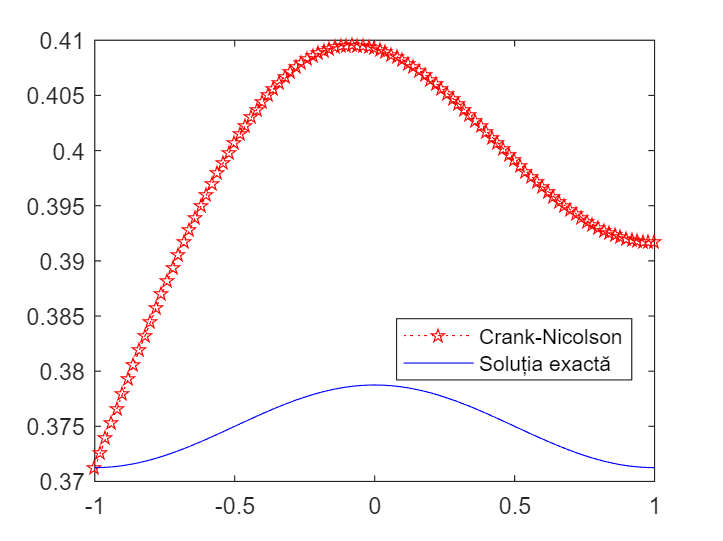

dt=0.001; dx=0.02; niu=dt/(dx*dx);
Nx=2/(dx)+1; x=-1:dx:1;
tf=0.5; Nt=tf/dt;
Uo=zeros(Nx,1);
Un=zeros(Nx,1);
for i=1:Nx
    if abs(x(i))<0.5
        Uo(i)=1-abs(x(i));
    elseif abs(x(i))==0.5
        Uo(i)=0.25;
    else 
        Uo(i)=0;
    end
end
%metoda Crank-Nicolson
A=zeros(Nx,Nx);
b=zeros(Nx,1);
n=0;
b(1)=solutiaExacta(-1,tf);
while (n<Nt)
    n=n+1;
    A(1,1)=1;
    for i=2:Nx-1
        A(i,i-1)=-niu;
        A(i,i)=2+2*niu;
        A(i,i+1)=-niu;
        b(i)=niu*Uo(i-1)+(2-2*niu)*Uo(i)+niu*Uo(i+1);
    end
    A(Nx,Nx)=1;
    A(Nx,Nx-1)=-1;
    b(Nx)=0;
    Un=A\b;
    Uo=Un;
end

plot(x,Uo,'p:r')
hold on
Ue=solutiaExacta(x,tf);
plot(x,Ue,'b')
legend('Crank-Nicolson', 'Soluția exactă', Location='best')
hold off

fprintf('Eroarea este %.16e.', norm(Ue'-Uo,Inf))

Eroarea este 3.1015713104709852e-02.

function rez=solutiaExacta(x,t)
    syms k
    s1=symsum(((-1)^k/(pi*(2*k+1))+2/(pi^2*(2*k+1)^2))...
            *cos(pi*(2*k+1).*x).*exp(-pi^2*(2*k+1)^2.*t),k,0,Inf);
    s2=symsum((cos(2*pi*(2*k+1).*x)/(pi^2*(2*k+1)^2).* ...
            exp(-4*pi^2*(2*k+1)^2.*t)),k,0,Inf);
    v1=double(s1);
    v2=double(s2);
    rez=3/8+v1+v2;
end